# Carbon Neutral

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

to address the challenges of climate change, many company, such as Mathworks, commited themselves to becoming carbon neutral. A fundamental component of this efforts is supporting the development of renewable energy. In this scripts, we will explore two renewable energy sources based on fluid system: hydropower and wind turbine.

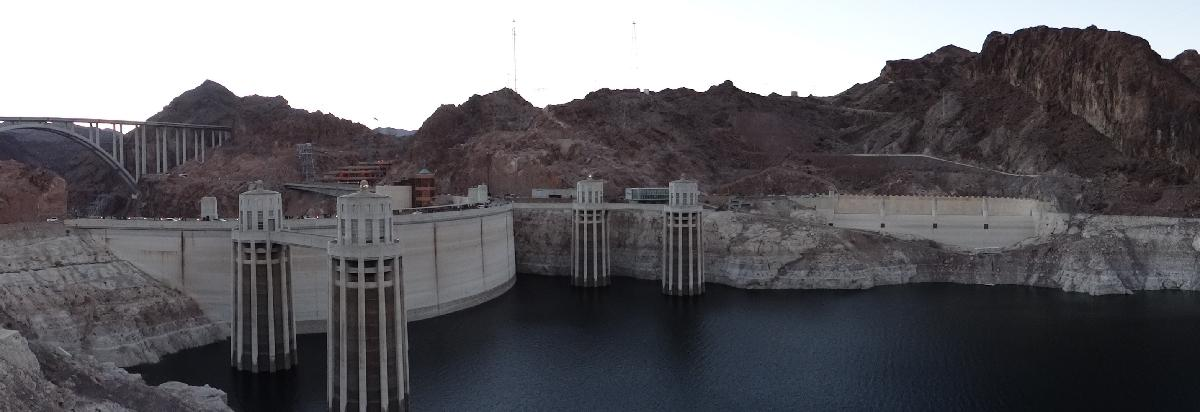

Hoover Dam intake tower from lake Mead, [USGS](https://www.usgs.gov/media/images/hoover-dam-intake-towers-panorama)

## Introduction

Fluid dynamics plays a significant role in the development and optimizaton of renewable energy technologies. For exmple the performance of a wind turbine is heavily influenced by the aerodynamic properties of the blades, fluid dynamics simulation are usually carried to optimized parameters such as the shape, size and angle of attack of the blades. 

In this script we will study wind turbine and hydroelectric power to generate enough electricity to power the data center running MATLAB Online.

### What is energy?

In a fluid, energy refers to the ability of a fluid to produce work. It takes various form:

- Kinetic energy refers to the energy of motion

- Potential energy refers to the energy associated with a conservative external fields such as gravity

- Internal energy refers to the molecular internal energy of the fluid

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Energy")

### What is power?

Power refers to the rate at which energy is transferred. It is typically measured in units of energy per unit of time, such as Watts (W) or horsepower (hp).

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Power")

### Problem presentation

[PICTURE DATA CENTER]

MathWorks pledge to become [carbon neutral by 2023](https://www.mathworks.com/company/aboutus/carbon-neutral.html). One of the big energy consumption of its headquarter in Natick, MA is the data center. In this script, we will study the possibility to offset this power consumption by generating renewable energy from either wind turbine of hydropower. We are considering that the data center maximum power consumption is 1300 kW. All data presented in this script are non representative of MathWorks actual power comsumption.

  **Try. **Load the data center power usage during 2022.

 
load DataCenter.mat
bar(dataCenter.date,dataCenter.avgPower)
ylabel("Average Monthly Power Consumption (kW)")
title("Data Center Power Consumption")

We can estimate to total energy consumption during each month with the following equation:


$$E_\text{month} = \bar{P} \Delta{t}$$


Where $E_\text{month}$ is the power consumption during a month, $\bar{P}$ is the average power consumption during the month and $\Delta t$ is the elapsed time during that month. 

 **Exercise. **Add a data entry in `dataCenter` corresponding to the total energy consumed during this month in kWh.

% Your code goes here:
dataCenter.energyUsage(:) = 0.0;

% Display the total annual energy consumption in kWh
units = symunit;
annualEnergyConsumption = sum(dataCenter.energyUsage) * units.kW*units.h

  CheckAnnualEnergyConsumpion(annualEnergyConsumption)

 **Reflect**. As a comparison, a laptop comsumes around 150 kWh per year, the energy comsumed by the data center could power over 30,000 laptop all year. At 0.14$/kWh of electricity, the electricity bill from using the data center is around $670,000 per year.

## Understanding Wind Turbine

In this section, we will focus on generating electricity for the data center using wind turbine. We know that the power of a fluid going through a surface can be calculated using the following relationship:


$$P = \frac{1}{2}\dot{m}V^2$$


where $P$ is the power, $\dot{m}$ is the mass flow and $V$ is the velocity. 

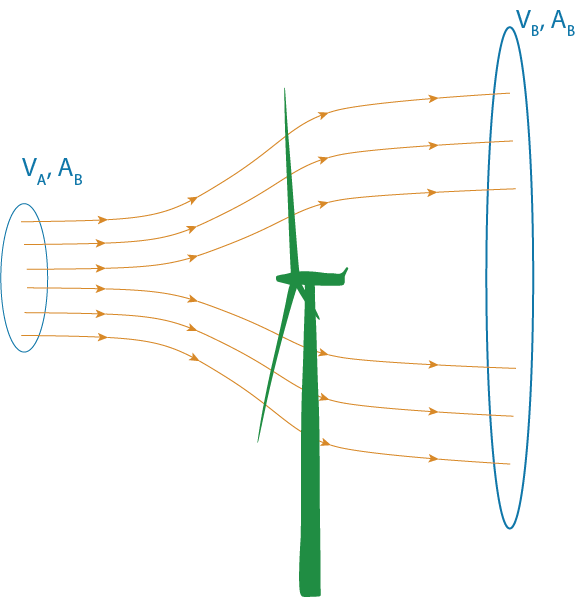

A power turbine of surface $S_t$, generates power by collecting the kinetic enegy from upstram air flow at velocity $V_A$ (m/s). The air flow is slowed down and exit the system downstream at velocity $V_B$. The wind speed at the turbine is $V_t$. The first approach to study this system is to apply the mass and momentum conservation equation to the control volume that encompass the streamline as presented in the previous figure. If you need to practice or refresh your knowledge on the control volume method, you should attempt to complete [ManOnTheMoon.mlx](matlab:open('./ManOnTheMoon.mlx')).

### **Control Volume**

#### **Mass Conservation**

We consider the control volume as describe as in the previous figure. All the mass flow coming in the control volume volume through the surface A, must exit the control volume through surface B. Therefore we can write the following mass flow equilibrium:


$$\rho S_A v_A = \rho S_B v_B = \rho S_t v_t = \dot{m}$$


where $\rho$ is the density, $(S_A,S_B,S_t)$ are the arar of surface A, B and the area of the turbine, and $(v_A,v_B,v_t)$ are the velocity of the flow through the surface A, B and the turbine itself.

  **Try. **Define the problem parameters (velocity, areas) and compute the mass flow through the turbine.

syms rhoAir surfaceA surfaceB surfaceT velocityA velocityB velocityT
massFlow = rhoAir*surfaceT*velocityT

#### **Momentum Conservation**

The momentum conservation equation can be expressed as:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV}_\text{Acceleration}
+
\underbrace{\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS}_\text{Thrust}
=
\sum\vec{F}$$


We are considering the flow to be at steady-state, so the derivative with respect to time is equal to zero. There is no radial flow, so all the air entering the turbine upstream is exiting the turbine downstream. Therefore, we are left with:


$$\int_\text{upstream}(\vec{v_A}\cdot\vec{n_A})\rho\vec{v_A} \; dS
+
\int_\text{downstream}(\vec{v_B}\cdot\vec{n_B})\rho\vec{v_B} \; dS
=
\vec{F}_\text{turbine\rightarrow air}$$


We are considering that the problem is one-dimensional along the horizontal axis:


$$\int_\text{upstream}(\vec{v_A}\cdot\vec{n_A})\rho v_A \; dS
+
\int_\text{downstream}(\vec{v_B}\cdot\vec{n_B})\rho v_B \; dS
=
F_\text{turbine\rightarrow air}$$


The upstream term can be expressed as:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho v \; dS
=
-\dot{m}v_A$$


 **Exercise. **Compute the expression of the force acting on the air from the turbine and its reciprocal.

% Your code goes here:
forceTurbineOnAir = 0.0;

% Simplify the expression:
forceAirOnTurbine = - forceTurbineOnAir;
if (forceTurbineOnAir ~= 0)
    forceAirOnTurbine = simplify(forceAirOnTurbine)
end

  %checkForceAirOnTurbine(forceAirOnTurbine)

We can express the power by:


$$P_\text{air\rightarrow turbine}=\frac{dE}{dt} = \frac{d(F_\text{air\rightarrow turbine}dx)}{dt}=\frac{dF_\text{air\rightarrow turbine}}{dt}dx + F_\text{air\rightarrow turbine}\frac{dx}{dt}$$


We are considering the force to be constant with time, therefore:


$$P_\text{air\rightarrow turbine} = F_\text{air\rightarrow turbine}\frac{dx}{dt}$$


Thus,


$$P_\text{air\rightarrow turbine}=F_\text{air\rightarrow turbine}v_t$$


 **Exercise. **Compute the power of the collected by the turbine.

powerCollected = simplify(forceAirOnTurbine*velocityT);

  checkPowerCollected(powerCollected)

#### Energy conservation

The conservation of energy can be expressed as:


$$\frac{\partial}{\partial t}\int_{CV} \rho e\; dV + \int_{CS} (\vec{u}\cdot\vec{n})\rho e\;dS=\dot{Q}-\dot{W}$$


Where, $e$ is the specific energy, $\dot{Q}$ is the rate of thermal energy brought to the system and $\dot{W}$is the rate of work. In our case, the system is considered at steady-state and there is no thermal energy brought to the system, therefore:


$$ \int_{CS} (\vec{u}\cdot\vec{n})\rho e\;dS=-\dot{W}_{\text{air}\rightarrow\text{turbine}}$$


The control volume only has fluid entering through disk A and exiting through disk B, therefore:


$$P_\text{air\rightarrow turbine} = P_A - P_b \quad\quad (\clubsuit)$$


With:


$$P_{A|B} = \int_{CV} \pm V_{A|B}\; \rho e \; dS$$


The specific energy can be expressed as:


$$e = \frac{V^2}{2} + gz + u$$


In our case, the internal energy $u$ and the elevation change are considered to be negligible compared the the kinetic energy term in the specific energy. Therefore, we consider:


$$e \approx\frac{V^2}{2}$$


Thus,


$$P_{A|B} = \pm\frac{1}{2}\dot{m}V_{A|B}^2$$


 **Exercise. **Compute the expression of the power available at disk A and disk B.

% Your code goes here:
powerA = 0;
powerB = 0;

 checkPowerAB(powerA, powerB)

 **Exercise. **Write $(\clubsuit)$ in p`owerBalance.`

powerBalance = 0 == 0;

 checkPowerBalance(powerBalance)

 **Exercise. **Solve the power balance $(\clubsuit)$ to find $V_t$ as a function of $V_A$ and $V_B$

velocitySoln = 0;

 checkVelocitySoln(velocitySoln)

 **Exercise. **Substitute $V_t$ for its correct solution function of $V_A$ and $V_B$ in the epression of the power of the air on the turbine

% Select the correct answer:
if velocitySoln ~= 0
    velocitySoln = velocitySoln(2);
end

% Your code goes in the next line:
powerCollected = powerCollected;

 checkPowerCollected2(powerCollected)

The power collected by the turbine is now a function of the upstream and downstream velocity.

### Wind turbine efficiency

In this subsection, we are studying the efficiency of the wind turbine. The efficiency can be expressed as the ratio in between the power collected by the turbine over the maximum power available to the turbine $\eta = \frac{P_\text{turbine }}{P_\text{max}}$.

The maximum available to the turbine should be equal to the power of the wind going to the surface of turbine if the turbine was not even built.

 **Exercise. **Define the maximum power that is available to the wind turbine.

% Your code goes here:
Power_max = 0;
 
 checkMaximumPower(Power_max)

 **Exercise. **Define the efficiency of the wind turbine

% Your code goes here:
eta_turbine = 0;

 checkTurbineEta(eta_turbine)

The power efficiency of the wind turbine only depends on two parameters, the upstream and downstream velocity. However, we also know that the downstream velocity is necessarly lower than the upstream velocity and both velocity are greater than zero. Therefore, we can study the efficiency of the turbine as a function of a parameter $x = \frac{V_\text{downstream}}{V_\text{upstream}}$, the ratio of velocity in between the downstream and upstream velocity. This parameter represents how much the air flow is slowed down by the wind turbine.

  **Try. **Run the following lines of code to express the efficiency of the turbine as a function of the parameter $x$.

syms x
eta_turbine = simplify(subs(eta_turbine, velocityB, x*velocityA))

  **Try. **Plot the the wind turbine efficiency as a function of parameter $x$.

% Plotting function
fplot(100*x,100*eta_turbine,[0 1])
xlabel("x (%)")
ylabel("\eta (%)")
title("Wind turbine efficiency")

 **Reflect**. It has a maximum, it is below one, so we can't collect the whole power coming from the upstream wind.

  **Try.** What is the maximum efficiency?

deta = diff(eta_turbine,x);
xmax = solve(deta == 0,x)
if xmax~=0
    xmax = xmax(2)
end

eta_max = subs(eta_turbine,x,xmax)

 **Reflect**. The equation presents two roots, one maximum at $x = 1/3$ for and efficiency just below 60%. The second root is $x=-1$, what would it mean physically? Is it possible?

### Estimation number of wind turbine required

Now that we know how much energy can be extracted by a wind turbine, we can use weather data from a weather station in Natick, MA to determine the energy that could potentially be collected by a wind turbine in this location.

  **Try.** Load and visualize the weather data.

load NatickWeather.mat
weather

  **Try.** Use the following slider to define the rotor span of the wind turbine, you could find some reference online.

turbineWingSpan = 55* units.meter;
S_turbine = pi*turbineWingSpan^2/4;
rho_air = 1.14*units.kg/units.meter^3;

For the rest of this script, we are considering that the wind turbine is operating with an efficiency $\eta=40\%$, which is inferior to the Betz limit to include the efficiency of the mechanical and electrical system. This efficiency is representative of a new high-efficiency wind turbine.

 **Exercise. **Using the dot notation, add a column to the weather table corresponding the the power extracted from the wind $P=\frac{\eta}{2}\rho S_t V_\text{wind}^3$

% Define the efficiency:
eta = 0.4;

% Your code goes here:
weather.powerExtracted(:) = 0;

  checkPowerExtractedTurbine(weather)

  **Try.** Based on your previous answer, we can compute the energy that is generated each day, the annual energy production and so the number of wind turbine that would need to be installed to power the data center.

% Compute the daily and annual energy produced by the wind turbine
weather.dailyProduction = weather.powerExtracted * 1*units.day;
turbineAnnualProduction = sum(weather.dailyProduction)
if turbineAnnualProduction ~= 0
    % Rewrite this energy in more common enregy unit, kWh
    turbineAnnualProduction = rewrite(turbineAnnualProduction, ["units.kWh"])
    
    % Compute the number of wind turbine that would need to be installed
    numberOfTurbine = annualEnergyConsumption/turbineAnnualProduction
end

 **Reflect**. Acceptability? Link to mathworks wind turbine farm in Oklahoma

## Understanding Hydropower

The second option considered to power MathWorks data center is to build a retention lake nearby the headquarter in Natick, MA. The water collected in this retention lake would be used to generate hyroelectricity. The design of the lake is inspired by MATLAB's logo.

  **Try. **Visualize the desing of the retention lake.

 
plotRetentionLake

### Creating a mathematical model

In order to model the power generated over a year by this installation, we are going to apply the conservation of mass to the control volume that is the lake. 


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho S_\text{lake} \; dh + \int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{lake}\frac{dh}{dt} + \int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{lake}\frac{dh}{dt} + \dot{m}_\text{rain} + \dot{m}_\text{evaporation} + \dot{m}_\text{turbine} = 0$$


In order to assure the sustainability of the water ressource, we are considering that the retention lake should constantly keep the same water heigth, therefore $\frac{dh}{dt} = 0$, and:


$$\dot{m}_\text{turbine} = - \dot{m}_\text{rain} - \dot{m}_\text{evaporation}$$


**Remark: **The different $\dot{m}$ are positive if the flow is leaving the control volume (*i.e. *the retention lake) and negative if the flow is entering the control volume. We can abandon that convention and consider all the mass flow positive. The previous equation become:


$$\dot{m}_\text{turbine} =  \dot{m}_\text{rain} - \dot{m}_\text{evaporation}$$


This equation describe that the mass flow through the turbine is equal to the mass flow received from the rain minus the mass flow of water evaporated. We are considering that the rain and evaporation mass flow are only dependent of the local weather and the dimension of the retention lake. 

  **Try.** Define the parameters of the problem `lakeLength` represents the length of the side of the lake, `surfaceLake` represents the surface of lake, rhoWater is the density of water in the lake, deltaH is the elevation difference in between the surface of the lake and the turbine, bassinArea represents the surface from which rain water is captured and injected into the retention lake.

 
lakeLength = 100*units.m;
surfaceLake = lakeLength^2;
rhoWater = 1000*units.kg/units.m^3;
deltaH = 10*units.m;
bassinArea = 1*units.km^2;

#### Modeling the rainfall

The water collected from the rainfall is modelled using real data collected from a custom weather station installed in one of the parking garage at MathWorks Apple Hill campus.

  **Try.** Load and visualize the weather data.

 
load NatickWeather.mat
weather

In this table the temperature is reported in degree Celsius, the wind in meter per second, the relative humidity is in percent, the rainfall is in millimeter and the dew point is in degree Celsius.

 **Exercise. **Using the dot operator,** a**dd a column to the table that represents the mass of water accumulating in the lake from the rainfall during each day, do not forget to assign a unit to the rainfall.

% Your code goes here:
weather.dailyMassRain(:) = 0;

% Show the annual rainfall in Natick in term of mass:
annualMassRain = sum(weather.dailyMassRain);
if annualMassRain ~= 0
    annualMassRain = simplify(sum(weather.dailyMassRain))
end

  checkAnnualRain(annualMassRain)

#### Model the evaporation

The evaporation of the lake is a function of the temperature, wind speed and relative humidity of the air. This 


$$\dot{m}_\text{evaporation} = (\alpha+\beta V_\text{wind})S_\text{lake}(W_s-W)$$


- 
$$\alpha = 600\;\text{kg}\cdot\text{m}^{-2}$$
 

- 
$$\beta=455 \;\text{kg}\cdot\text{m}^{-3}\cdot\text{s}$$


$W$ and $W_s$ are the humidity ratio and the maximum humidity ratio defined by the following formula:


$$W = 0.62198 \frac{P_w}{P-P_w}$$



$$W_s = 0.62198\frac{P_s}{P-P_s}$$


where $P$ is the atmospheric pressure, consider to be equal to 101325 Pa, $P_w$ is the partial pressure of water in the air, and $P_s$ is the saturation pressure of water. The saturation pressure can be approximated using Antoine's equation:


$$log_{10}(P_s) = A - \frac{B}{C+T}$$


- 
$$A=8.07131$$


- 
$$B=1730.63$$


- 
$$C=233.426$$
 

When using Antoine's equation, one has to be careful with the unit as the temperature is considered in degree Celsius and the saturation pressure in millimeter of mercury (mmHg).

 **Exercise. **Compute the saturation pressure based on Antoine's equation, don't forget to add the units!

% Antoine's equation parameters:
A = 8.07131;
B = 1730.63;
C = 233.426;

% Your code goes here:
weather.saturationPressure(:) = 0;

% Answer check/hints:
 checkSaturationPressure(weather)

The partial pressure of water in the air can be computed using the following relation:


$$RH = \frac{P_w }{ P_s}$$


 **Exercise. **Convert this energy use in kWh

% Your code goes here
weather.waterPressure(:) = 0;

% Answer check/hints:
 checkWaterPressure(weather)

  **Try.  **Compute $W$ and $W_s$ are the humidity ratio and the maximum humidity ratio.

weather.W = simplify(0.62198*weather.waterPressure./(101325*units.Pa-weather.waterPressure));
weather.Ws = simplify(0.62198*weather.saturationPressure./(101325*units.Pa-weather.waterPressure));

The mass flow of water lost due to evaporation can now be estimated using the followin relation:


$$\dot{m}_\text{evaporation} = (25+19 V_\text{wind})S_\text{lake}(W_s-W)$$


weather.massEvaporation = units.kg/units.m^2*(600+455*weather.Wind).*surfaceLake.*(weather.Ws-weather.W);
totalWaterEvaporated = sum(weather.massEvaporation)

  **Try. **Compute the total energy that could be generated from this retention lake

totalWaterAvailable = annualMassRain - totalWaterEvaporated  % Total water available to produce energy
totalEnergy = rewrite(totalWaterAvailable*10*units.mH2O, [units.kWh])/rhoWater % Total Energy that could be produced
ratio = totalEnergy / annualEnergyConsumption % Ratio of the annual consumption that would be covered

## Further exploration

[https://www.mathworks.com/help/sps/ug/wind-turbine.html](https://www.mathworks.com/help/sps/ug/wind-turbine.html)

- hydropower was not adapted

- Check the characteristic of major hydropower facility such as the Hoover Dam (wikipedia link)

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

## Helper Functions

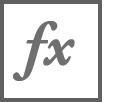`CheckAnnualEnergyConsumpion(annualEnergyConsumption)`

function CheckAnnualEnergyConsumpion(annualEnergyConsumption)
    arguments
       annualEnergyConsumption (1,1) sym 
    end

    % Compute the right answer
    units = symunit;
    load DataCenter.mat
    dataCenter.energyUsage = dataCenter.avgPower.*dataCenter.numberOfDay*24;
    rightAnswer = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Compute wrong answer if delta t was in seconds
    dataCenter.energyUsage = dataCenter.avgPower.*dataCenter.numberOfDay*24*3600;
    wrongSecond = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Forgot number of hour
    dataCenter.energyUsage = dataCenter.avgPower.*dataCenter.numberOfDay;
    wrongHour = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Forgot number of day
    dataCenter.energyUsage = dataCenter.avgPower.*24;
    wrongMonth = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Forgot delta T
    dataCenter.energyUsage = dataCenter.avgPower;
    wrongDT = sum(dataCenter.energyUsage)*units.kW*units.h;
    
    if isequal(rightAnswer,annualEnergyConsumption)
        disp("Good job! You computed the total annual energy consumption correctly.")
    else
        if isequal(wrongSecond, annualEnergyConsumption)
            warning("Your reasonning is right, however your unit is wrong, make sure to express the time in hour not seconds.")
        elseif isequal(wrongHour, annualEnergyConsumption)
            warning("Your reasonning is right, however it appears that you forgot to multiply by the number of hour in a day.")
        elseif isequal(wrongMonth, annualEnergyConsumption)
            warning("Your reasonning is right, however it appears that you forgot to multiply by the number of day in a month.")
        elseif isequal(wrongDT, annualEnergyConsumption)
            warning("You forgot to multiply the average power consumption by a unit of time. Hint: this time has to be express in hours.")
        else
            warning("Please complete the line of code indicated in the comment.")
        end
    end
end

`checkForceAirOnTurbine(answer)`

function checkForceAirOnTurbine(answer)
    arguments
        answer (1,1) sym
    end
    
    % Define the solution
    syms rhoAir velocityT surfaceT velocityA velocityB
    massFlow = rhoAir*velocityT*surfaceT;
    solution =  simplify(massFlow*velocityA - massFlow*velocityB);
    
    if isequal(answer, solution)
        disp("Good job! You define the force applied by the air on the turbine correctly!")
    else
        if isequal(answer, -solution)
            warning("Your reasoning is correct, however you are comitting a sign error.")
        else
            warning("There is an error in your computation. Hint: while the integral over"+...
                " the surface A resulted in a negative sign, the integral over surface B should"+...
                " results in a positive sign.")
        end
    end

end

`checkPowerAB(answerA,answerB)`

function checkPowerAB(answerA,answerB)
    arguments
        answerA (1,1) sym
        answerB (1,1) sym
    end
    
    syms rhoAir surfaceA surfaceB surfaceT velocityA velocityB velocityT
    rightAnswerA = 1/2*rhoAir*surfaceT*velocityT*velocityA^2;
    rightAnswerB = 1/2*rhoAir*surfaceT*velocityT*velocityB^2;

    if ~isequal(answerA,rightAnswerA)
        warning("You should expressed the power at poin A as a function of"+...
            " the mass flow and velocity at point A.")
    end
    if ~isequal(answerB,rightAnswerB)
        warning("You should expressed the power at poin B as a function of"+...
            " the mass flow and velocity at point B.")
    end
    
    if isequal(answerA,rightAnswerA) && isequal(answerB,rightAnswerB)
        disp("Good job! You defined the power at point A and B correctly.")
    end

end

`plotRetentionLake()`

function plotRetentionLake()
    Z = membrane(1,10);
    Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
    n = size(Z,1);
    [X,Y] = meshgrid(0:n-1,0:n-1);
    X = 2*X/(n-1) - 1;
    Y = 2*Y/(n-1) - 1;
    C = zeros(size(Z));
    C(11:31,11:31) = 1.0;
    Z(1,:) = 0.0;
    Z(end,:) = 0.0;
    Z(:,1) = 0.0;
    Z(1,end) = 0.0;
    Z( Z < 0 ) = 0.0;
    X = X * 100;
    Y = Y * 100;
    s = surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
    view([-64 59])
    mapFace = [0.3 0.3 0.3
               0.83 0.94 0.97];
    colormap(mapFace)
end

`checkPowerCollected(answer)`

function checkPowerCollected(answer)
    arguments
        answer (1,1) sym
    end

    syms rhoAir surfaceA surfaceB surfaceT velocityA velocityB velocityT
    rightAnswer = rhoAir*surfaceT*velocityT^2*(velocityA-velocityB);

    if isequal(answer,rightAnswer)
        disp("Good job! You calculated the power collected correctly.")
    else
        warning("The power collected should be expressed as the velocity through "+...
            "the turbine mulitplied by the force acting on the turbine.")
    end
       
end

`checkPowerBalance(answer)`

function checkPowerBalance(answer)
    arguments
        answer (1,1) sym
    end

    syms rhoAir surfaceT velocityA velocityB velocityT
    rightAnswer = rhoAir*surfaceT*velocityT^2*(velocityA-velocityB) ==...
        1/2*rhoAir*surfaceT*velocityA^2*velocityT -...
        1/2*rhoAir*surfaceT*velocityB^2*velocityT;

    if isequal(rightAnswer,answer)
        disp("Good job! You defined the power balance correctly.")
    else
        warning("The power balance should be defined as the power collected being equal"+...
            " to the difference of the upstream and downstram power.")
    end

end

`checkVelocitySoln(answer)`

function checkVelocitySoln(answer)
    arguments
        answer (:,:) sym
    end
    syms velocityA velocityB
    rightAnswer = sym('r', [1; 2])';
    rightAnswer(1) = 0;
    rightAnswer(2) = 1/2*(velocityA+velocityB);

    if isequal(answer,rightAnswer)
        disp("Good job! You found demonstrated that the velocity through the turbine is the "+...
            "average of the upstream and downstream velocity.")
    else
        warning("Hint: use the function solve!")
    end

end

`checkPowerCollected2(answer)`

function checkPowerCollected2(answer)
    arguments
        answer (1,1) sym
    end

    syms rhoAir surfaceT velocityA velocityB velocityT
    rightAnwer = rhoAir*surfaceT*(1/2*velocityA+1/2*velocityB)^2*(velocityA-velocityB);

    if isequal(answer,rightAnwer)
        disp("Good job! You found the expression of the power collected as a function of "+...
            "the upstream and downstream velocity.")
    else
        warning("Use the function subs to substitute the velocity of a turbine with its "+...
            "expression as a function of the upstream and downstream velocity defined in "+...
            "the previous exercise.s")
    end
end

`checkMaximumPower(answer)`

function checkMaximumPower(answer)
    arguments
        answer (1,1) sym
    end

    syms rhoAir surfaceT velocityA
    rightAnswer = 1/2*surfaceT*rhoAir*velocityA^3;

    if isequal(answer,rightAnswer)
        disp("Good job! You defined the maximum to be collected by the turbine correctly.")
    else
        warning("The maximum power to be collected would be the power going through the turbine "+...
            "rotor disk if the turbine was not there.")
    end

end

`checkTurbineEta(answer)`

function checkTurbineEta(answer)
    arguments
        answer (1,1) sym
    end

    syms velocityA velocityB
    rightAnswer = 1/2*(velocityA+velocityB)^2*(velocityA-velocityB)/(velocityA^3);
    
    if isequal(answer,rightAnswer)
        disp("Good job! You defined the turbine efficiency correctly.")
    else
        warning("Hint: The turbine effiency is the ratio of the power collected by the turbine "+...
            " over the maximum power to be collected.")
    end
end

`checkAnnualRain(answer)`

function checkAnnualRain(answer)
    arguments
        answer (1,1) sym
    end

    if 0.9*6.7475e+08 <= separateUnits(answer) && separateUnits(answer) <= 1.1*6.7475e+08 
        disp("Good job! The mass of annual rain was defined correctly.")
    else
        warning("The mass of water can be compute the a density times the annual volume of water.")
    end

end

`checkSaturationPressure(answer)`

function checkSaturationPressure(answer)
    rightMean = 12.3840;
    answerMean = mean(separateUnits(answer.saturationPressure));

    if 0.9*rightMean <= answerMean && answerMean <= 1.1*rightMean
        disp("Good job! The saturation pressure was defined correctly.")
    else
        warning("You can compute the saturation pressure using Antoine's"+...
            " equation introduced previously")
    end
    
end

`checkWaterPressure(answer)`

function checkWaterPressure(answer)
    rightMean = 8.6823;
    answerMean = mean(separateUnits(answer.waterPressure));

    if 0.9*rightMean <= answerMean && answerMean <= 1.1*rightMean
        disp("Good job! The water pressure was defined correctly.")
    else
        warning("You can compute the water pressure based on the saturation "+...
            "pressure and the relative humdity.")
    end

end

`checkPowerExtractedTurbine(answer)`

function checkPowerExtractedTurbine(answer)
    
    rightMean = 7.3067e+3;
    answerMean = mean(separateUnits(answer.powerExtracted));

    if 0.9*rightMean <= answerMean && answerMean <= 1.1*rightMean
        disp("Good job! The power corrected was defined correctly.")
    else
        warning("You can compute the power extracted based on the wind speed "+...
            "and the expression developped in the previous section of this script.")
    end
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc